clear all
rng(14)

nspec = 3;
nm = 2;
np = 2;
p_length = 100;

polys = zeros(np, nm);
for i = 1:np
    polys(i, :) = create_poly(p_length, nm);
end

polys

polys =     52    48
    59    41



cons_traits_mono = rand(nspec, nm);
cons_traits_mono = cons_traits_mono ./ sum(cons_traits_mono, 2)

cons_traits_mono =     0.1235    0.8765
    0.9321    0.0679
    0.3659    0.6341



C = zeros(nspec, np);
for i = 1:nspec
    C(i, :) = sum((polys' .* cons_traits_mono(i, :)')', 2);
end

C = (C * nm) / 50

C =     1.9398    1.7289
    2.0691    2.3111
    1.9785    1.9034



params.nspec = nspec;
params.np = np;
params.alpha = 0 * ones(nspec, 1);
params.r = 500 * ones(np, 1);
params.K = ones(np, 1);
params.m = 0.2 * ones(nspec, 1);
params.C = C;

init_abuns = ones(1, params.nspec) * 5;
init_res = ones(1, params.np) * 5;
init_state = [init_abuns, init_res];

tspan = [0 10000];
[t, sim] = ode45(@(t, y) macarthur_eqns(t, y, params), tspan, init_state);

eql = sim(end, :);
eql_abuns = eql(1:nspec);
num_coexist = sum(eql_abuns > 1)

num_coexist = 1

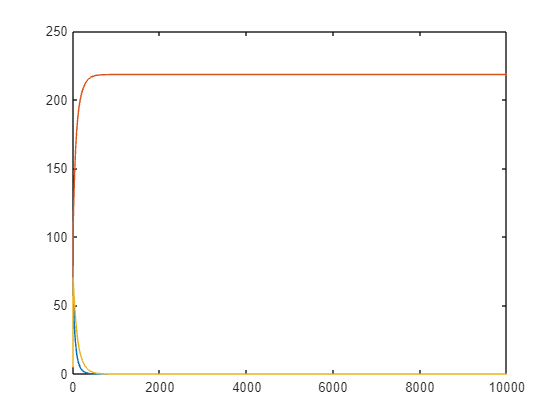


plot(t, sim(:,1:nspec))


row_tots = sum(C,2)

row_tots =     3.6687
    4.3803
    3.8820


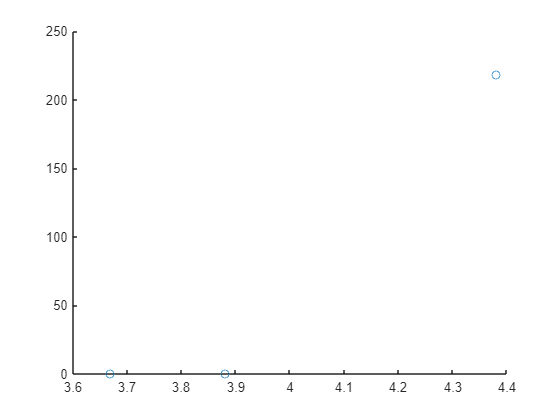


scatter(row_tots, eql_abuns)

corr(row_tots(:), eql_abuns(:))

ans = 0.9564

function counts = create_poly(p_length, nm)
    vec = randi(nm, 1, p_length);
    counts = histcounts(vec, 1:(nm+1));
end

function dydt = macarthur_eqns(~, state, params)
    N = state(1:params.nspec);
    R = state((params.nspec + 1):end);

    dNdt = params.alpha + N .* ((params.C * R) - params.m);
    dRdt = R .* (params.r .* (1 - R ./ params.K) - (params.C' * N));
    
    dydt = [dNdt; dRdt];
end